**7.**

%% Load Image Dataset
imds=imageDatastore('./q7_image/office_images','IncludeSubfolders', ...
                      true,'LabelSource','foldernames');

% inspect the number of images per category
table=countEachLabel(imds)

table = 5×2 table
      Label       Count
    __________    _____

    backpack       10  
    calculator     10  
    pen            10  
    printer        10  
    scissors       10  


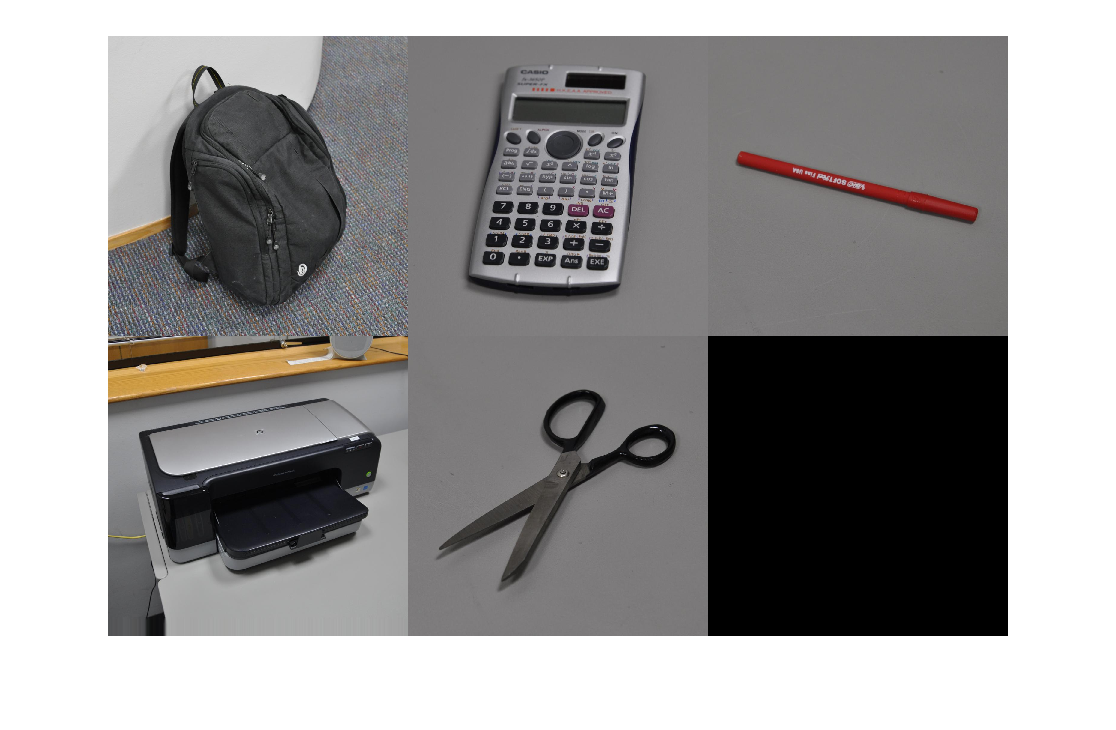

% visualization
figure
montage(imds.Files(1:10:end))

%% Split into Training and Validation Image Sets with a ratio of 6:4
[trainingSet, validationSet] = splitEachLabel(imds, 0.6, 'randomize');

%% Create a Visual Vocabulary and Train an Image Category Classifier

% Creating Bag-Of-Features.
bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: backpack
* Image category 2: calculator
* Image category 3: pen
* Image category 4: printer
* Image category 5: scissors
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 30 images...done. Extracted 1875000 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 1500000
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 52/100 iterations (~10.00 seconds/iteration)...converged in 52 iterations.

* Finished creating Bag-Of-Features




% Encoding images using Bag-Of-Features.
img = readimage(imds, 2);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


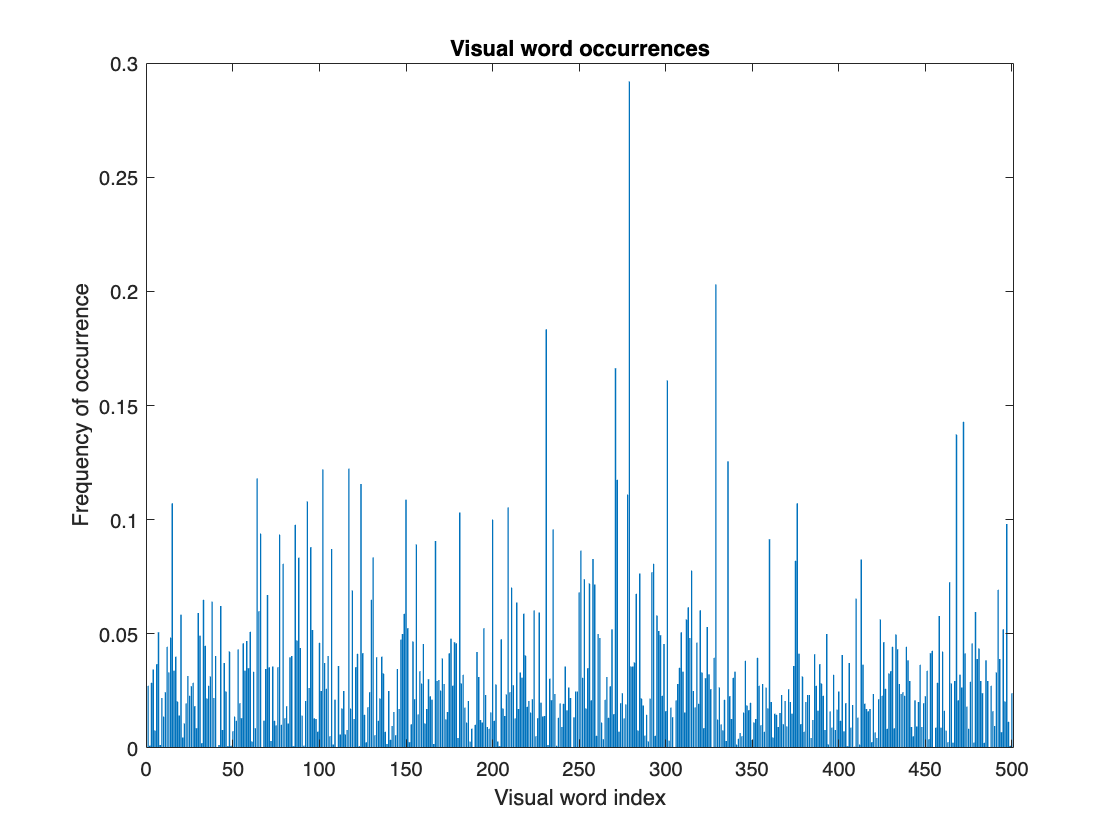


% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

%% Training an image category classifier for 5 categories.
categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: backpack
* Category 2: calculator
* Category 3: pen
* Category 4: printer
* Category 5: scissors

* Encoding features for 30 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



%% Model Evaluation

% Evaluate classifier performance on training set
confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: backpack
* Category 2: calculator
* Category 3: pen
* Category 4: printer
* Category 5: scissors

* Evaluating 30 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                     PREDICTED
KNOWN         | backpack   calculator   pen    printer   scissors   
--------------------------------------------------------------------
backpack      | 1.00       0.00         0.00   0.00      0.00       
calculator    | 0.00       0.83         0.00   0.17      0.00       
pen           | 0.00       0.00         1.00   0.00      0.00       
printer       | 0.00       0.00         0.00   1.00      0.00       
scissors      | 0.00       0.17         0.00   0.00      0.83       

* Average Accuracy is 0.93.




% Evaluate classifier on validation set
confMatrix_val = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: backpack
* Category 2: calculator
* Category 3: pen
* Category 4: printer
* Category 5: scissors

* Evaluating 20 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                     PREDICTED
KNOWN         | backpack   calculator   pen    printer   scissors   
--------------------------------------------------------------------
backpack      | 1.00       0.00         0.00   0.00      0.00       
calculator    | 0.00       1.00         0.00   0.00      0.00       
pen           | 0.00       0.00         1.00   0.00      0.00       
printer       | 0.00       0.00         0.00   1.00      0.00       
scissors      | 0.00       0.50         0.50   0.00      0.00       

* Average Accuracy is 0.80.




% Compute average accuracy
avg_acc = mean(diag(confMatrix_val));

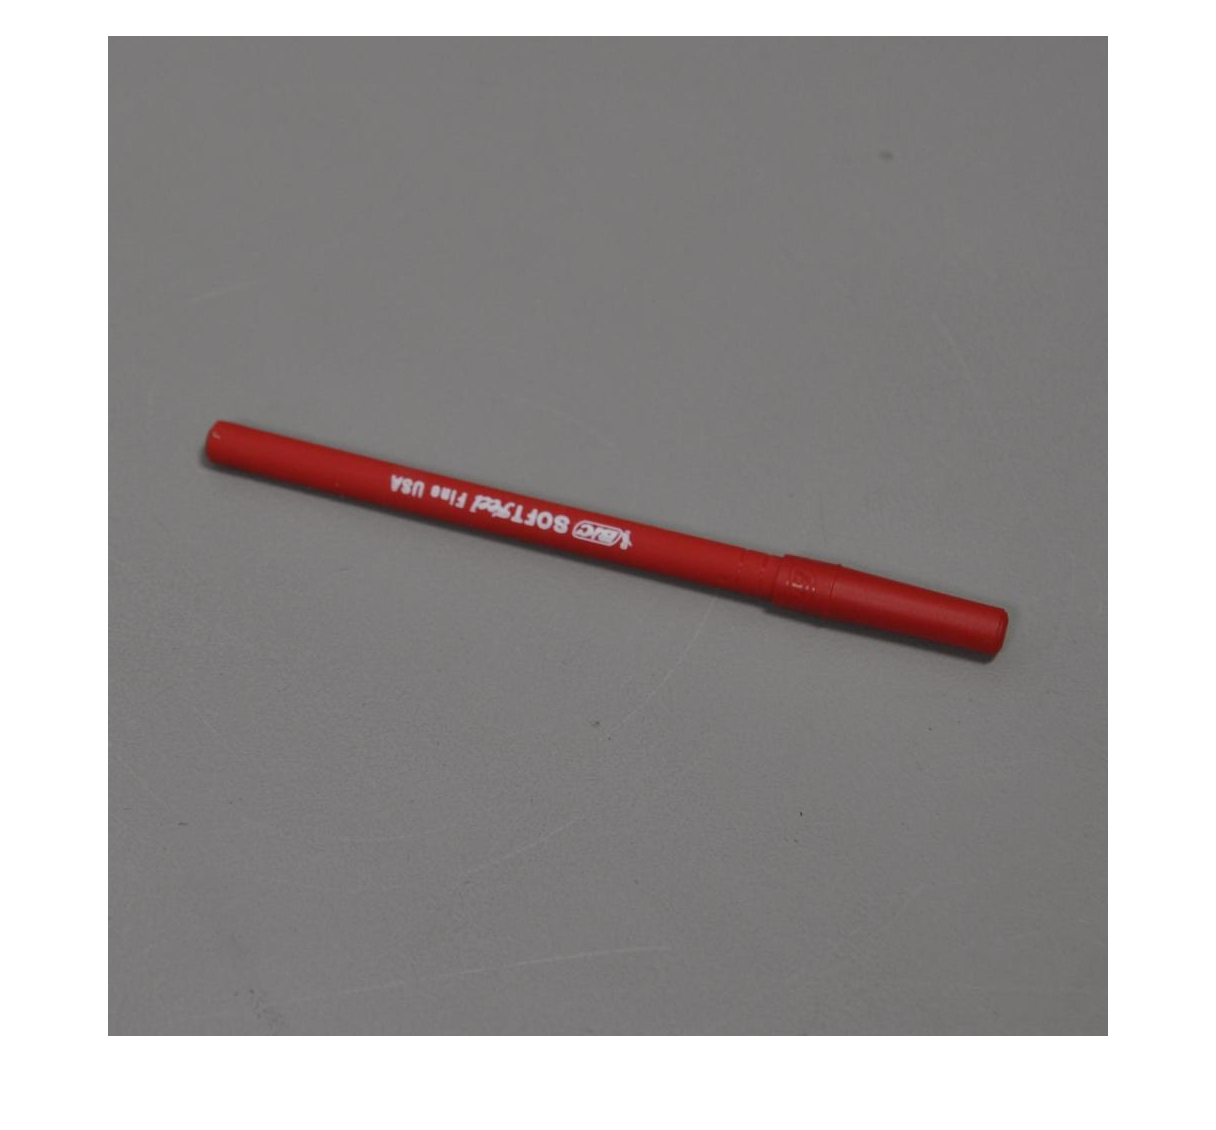

%% instance study
% read an image
img = imread(fullfile('./q7_image/office_images','pen','frame_0001.jpg'));
figure
imshow(img)

% run classification
[labelIdx, scores] = predict(categoryClassifier, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


pred = categoryClassifier.Labels(labelIdx);
disp(pred)

    {'pen'}



% The prediction is correct